# AI Model Music Example: Legends vs. Newcomers

## Step 1: Define Success

In this example, we’ll be using the albums of three successful rappers (Eminem, Jay-Z, and Kendrick Lamar) and Veeze, a rapper who released his debut studio album in 2023. Our goal is to compare the albums of the three successful rappers to Veeze’s debut album to determine if he will be as successful as these legends of rap music. The analysis of the albums will focus on two key features of each song: duration and danceability.

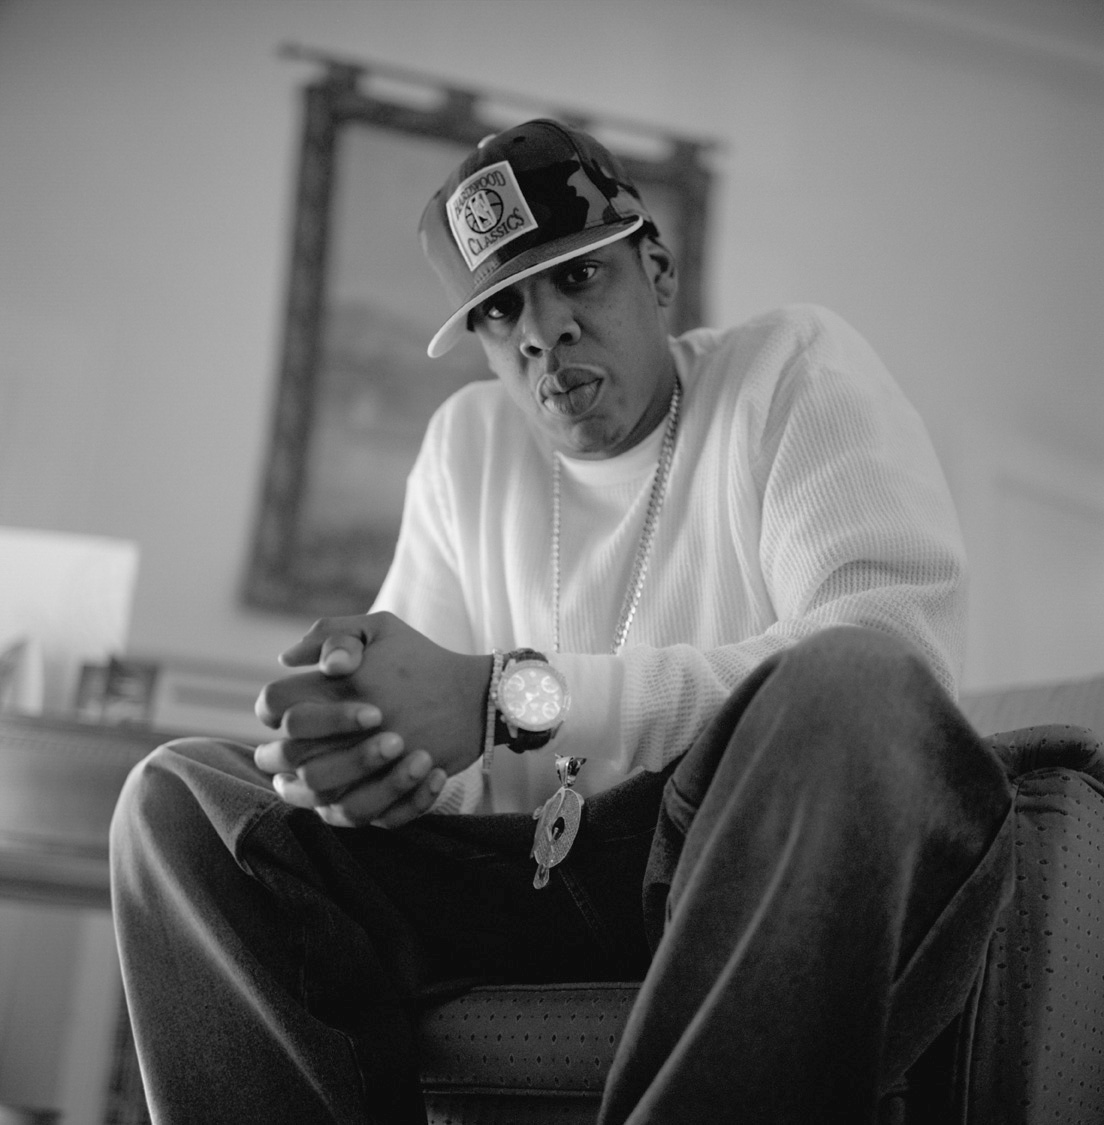

"[Jay-Z-02-mika](https://commons.wikimedia.org/w/index.php?curid=18630482)" by [Mikamote](https://commons.wikimedia.org/wiki/User:Mikamote) is licensed under [CC BY-SA 3.0](https://creativecommons.org/licenses/by-sa/3.0/?ref=openverse).

## Step 2: Import Your Music Data

We will get the data necessary from the [Spotify API](https://developer.spotify.com/documentation/web-api).

The two endpoints we'll use are: 

- **'https://api.spotify.com/v1/albums/{album id}/tracks' **to access the artist's name, duration, and track ids in each album. 

- **'https://api.spotify.com/v1/audio-features/{track id}' **to access each tracks unique features such as danceability. 

From the second endpoint you can access many interesting metrics such as the song's energy, instrumentalness, liveness, and other song characteristics. It is recommend that you explore this endpoint in the Spotify website since it might be useful when designing your own AI model. 

The code below consists of 3 major sections. In the first code block we will get an access token for the API. Once we have access we will retrieve 4 albums one for each artists. Finally, we access the song's unique features to get its danceability. 

% RUN THIS CODE AS IS TO GET ACCESS TOKEN
clc; clear;

% Copy in your own credentials.
clientID = 'YOUR ID'; % Replace with your actual client ID
clientSecret = 'YOUR ID'; % Replace with your actual client secret

% Create the URL for token retrieval
url = 'https://accounts.spotify.com/api/token';

% Encode the client ID and client secret in base64
authString = matlab.net.base64encode([clientID ':' clientSecret]);

% Set the options for the HTTP request
options = weboptions('RequestMethod', 'post', 'MediaType', ...
    'application/x-www-form-urlencoded','HeaderFields', {'Authorization', ['Basic ' authString]});

% Set the POST data
postData = 'grant_type=client_credentials';

% Make the POST request to retrieve the access token
response = webwrite(url, postData, options);

% Extract the access token from the response
Token = response.access_token;

% Display the access token (you can process it further as needed)
disp(['Access Token: ' Token]);

Access Token: BQCzLnx3SOZl32MoeLol7wPmxVQ1QJ1dffyGfiwYt2bwGTpS2Jm9PVmk8BbAwb8JLeFbSkn0hVbkmXHYLNsz_M-YS6n349monMC8rWhu78Hx2sVCfwI


The next code block will retrieve albums for each of the artists using the album ID in the table below. The albums in white rows will be used as training data  and the rows in blue will be used to verify the accuracy of the model. Veeze's album will only be used to compare his music to the music of the other 3 artists. 

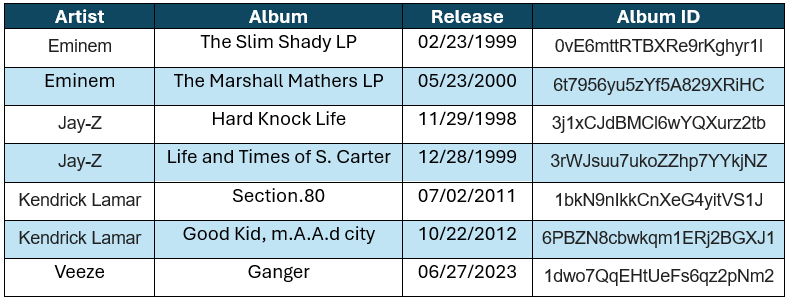

The code will also extract the name of the artist, duration of each song, and the track ID of each song. The track ID is a unique string of characters that Spotify uses to identify each song. The track ID is needed to retrieve each track's unique audio features, such as danceability. 

The segment below is missing variables to store the data retrieved from the API. Create two vector arrays one called `durations `to store the songs durations and one called `danceability` to store the danceability score of each song. 

% Stores the album' IDs 
% The order in which IDs are stored in the variable affects the order they are retrieved in. 
% The first 4 IDs are for the albums in the white rows of the table above and the
% last 3 IDs are for the albums in the blue rows.
albumIDs = {'0vE6mttRTBXRe9rKghyr1l';'3j1xCJdBMCl6wYQXurz2tb';'1bkN9nIkkCnXeG4yitVS1J';'1dwo7QqEHtUeFs6qz2pNm2';
    '6t7956yu5zYf5A829XRiHC'; '3rWJsuu7ukoZZhp7YYkjNZ'; '6PBZN8cbwkqm1ERj2BGXJ1'};

% Initialize arrays to store song details
allArtists = {};
TrackIDs = {};
durations = [];
danceability = [];

% Loop over each album ID
for j = 1:numel(albumIDs)
    % Construct the URL for getting the tracks of the album
    url = ['https://api.spotify.com/v1/albums/', albumIDs{j}, '/tracks?limit=50'];
    % Set up the web options with the access token
    options = weboptions('HeaderFields', {'Authorization', ['Bearer ', Token]});
    % Make the GET request to retrieve tracks of the album
    response = webread(url, options);

    % Get artist name, song duration, and track ID
    for i = 1:response.total
        allArtists = [allArtists; response.items(i).artists.name];
        durations = [durations;response.items(i).duration_ms];
        TrackIDs = [TrackIDs; response.items(i).id];
    end
end
disp('Albums retrieved successfully!')

Albums retrieved successfully!


This for loop will retrieve the danceability of each song using the track ids stored in the variable `TrackIDs`. Fill in the missing code to make the for loop function correctly. 

**Note: **This section might run slowly since it is having to complete 117 iterations. Be patient and only click the run button once. The statement "`Track danceability has been retrieved!"` will be printed when the code works properly. 

% Loop over each track to get its audio features
for k = 1:numel(TrackIDs)
    url2 = ['https://api.spotify.com/v1/audio-features/', TrackIDs{k}];
    options2 = weboptions('HeaderFields', {'Authorization', ['Bearer ', Token]});
    Features = webread(url2, options2);
    danceability = [danceability;Features.danceability];
end
disp('Track danceability has been retrieved!')

Track danceability has been retrieved!


Let's organize the data retrieved from the API. The code below will fix the names of the artists and store the data in a table. 

% Some songs were collaborations so they include more names than one.
% We only want the variable allArtists to contain the names of the main
% artists: 'Eminem','Jay-Z', 'Kendrick Lamar, & 'Veeze'.
allArtists(1:20) = {'Eminem'}; 
allArtists(71:88) = {'Eminem'};
allArtists(21:34) = {'Jay-Z'};
allArtists(89:104) = {'Jay-Z'};
allArtists(35:49) = {'Kendrick Lamar'};
allArtists(105:117) = {'Kendrick Lamar'};
allArtists(50:70) = {'Veeze'};

% Store the training data for Eminem, Jay-Z, and Kendrick Lamar. This will only
% consist of rows 1 to 49.
SongDetails = table(allArtists(1:49), durations(1:49), danceability(1:49));
disp('Table has been made sucessfully!')

Table has been made sucessfully!


## Step 3: Identifying Your Variables

In this example, we identified our variables as song duration and danceability in step one. 

## Step 4: Split Data Into Training & Testing Sets

In step 2, we decided that songs from the albums *The Slim Shady LP, Hard Knock Life, *and *Section.80 *were going to be used to train the model. We also decided that songs from the albums *The Marshall Mathers LP, Life And Times Of S. Carter*, and *Good Kid, m.A.A.d city *were going to be test data. 

The code below takes the data from the table `SongDetails` and separates it into the desired files. It also stores the data for Veeze into a file called `NewRapper`. In the segment below, write a line a code to convert `SongDetails` into an Excel file named `Rappers3.xlsx `using `writetable()`. Copy a the same line to covert `SongDetails2 `into an Excel file named `NewRapper.xlsx`.

% Names each column in the table
SongDetails.Properties.VariableNames = {'Artist', 'Duration', 'Danceability'};
% Converts table to an Excel file
writetable(SongDetails, 'Rappers3.xlsx');

% Store the data for Veeze. His data is in rows 50 to 70. 
SongDetails2 = table(allArtists(50:70), durations(50:70), danceability(50:70));
SongDetails2.Properties.VariableNames = {'Artist', 'Duration', 'Danceability'};
writetable(SongDetails2, 'NewRapper.xlsx');

% Store the testing data for Eminem, Jay-Z, and Kendrick Lamar. This will only
% consist of rows 71 to 117.
SongDetails = table(allArtists(71:117), durations(71:117), danceability(71:117));
SongDetails.Properties.VariableNames = {'Artist', 'Duration', 'Danceability'};
writetable(SongDetails, 'TestData.xlsx');
disp('Excel files have been created!')

Excel files have been created!


## Step 5: Finding Your Model

The type of model selected depends on whether you define success as a continuous value or as a category. The two main types of models are regression and classification models. In this example we wish to compare Veeze's songs to the songs of 3 successful rappers, so a classification model is the best option. 

In section 05, we learned that if you’re trying to classify a new genre or artist the KNN model is a good option since it is a straightforward model that adapts well to various problems. The functions needed to use the KNN model in MATLAB are `fitknn()` and `predict()`. In the next step we will use `fitknn() `train the model. 

## Step 6: Fitting a Model to Your Data

Let's fit a KNN model using the data in the file `Rappers3.xlsx`. We will make sure that model is working by using the function `predict() `to predict an artist based on a song duration of 333226 and danceability of 0.8. Who is the artist the model predicted? If you are curious to see if this is correct go to the data in `Rappers3.xlsx `and find which artist has a song with a duration of 333226 milliseconds. 

% Read the file and store the data into the variable 'Rappers3'.
Rappers3 = readtable("Rappers3.xlsx");

% Fit a k-nearest neighbors (KNN) classification model using the data
% and save in the variable 'knnmodel'. Set the NumNeighbors option to 6
knnmodel = fitcknn(Rappers3, "Artist", "NumNeighbors", 6);

% Test the model by making prediction based on duration and danceability data
% and store the result in the variable 'predicted'. 
predicted = predict(knnmodel, [33226, 0.8])

predicted = 1×1 cell array
    {'Eminem'}


## Step 7: Run Model Using Your Test Dataset

Let's apply the model to our test data, so that we can evaluate the models accuracy in step 8. First, write a line of code that reads the data in the file `TestData.xlsx `and stores it a variable called `TestData`.

% Read the verification data from the Excel file into a table
TestData = readtable('TestData.xlsx');

% Use the trained KNN model to predict the artists for the verification data
predictions = predict(knnmodel, TestData)

predictions = 47×1 cell array
    {'Eminem'        }
    {'Jay-Z'         }
    {'Jay-Z'         }
    {'Eminem'        }
    {'Kendrick Lamar'}
    {'Eminem'        }
    {'Jay-Z'         }
    {'Jay-Z'         }
    {'Kendrick Lamar'}
    {'Jay-Z'         }
    {'Jay-Z'         }
    {'Eminem'        }
    {'Jay-Z'         }
    {'Eminem'        }
    {'Jay-Z'         }
    {'Jay-Z'         }
    {'Jay-Z'         }
    {'Jay-Z'         }
    {'Kendrick Lamar'}
    {'Eminem'        }
    {'Jay-Z'         }
    {'Eminem'        }
    {'Jay-Z'         }
    {'Eminem'        }
    {'Eminem'        }
    {'Eminem'        }
    {'Eminem'        }
    {'Eminem'        }
    {'Jay-Z'         }
    {'Eminem'        }


## Step 8: Evaluate the Model

Let's evaluate the model by calculating the accuracy, misclassification rate, and making a confusion matrix. To calculate the accuracy we compare the predictions from the previous step to the data in the file `TestData.xlsx`.

% Check if the predictions are correct and calculate accuracy
iscorrect = cellfun(@isequal, predictions, TestData.Artist);
accuracy = sum(iscorrect) / numel(predictions)

accuracy = 0.2128


% Calculate misclassification rate
iswrong = ~cellfun(@isequal, predictions, TestData.Artist);
misclassrate = sum(iswrong) / numel(predictions)

misclassrate = 0.7872

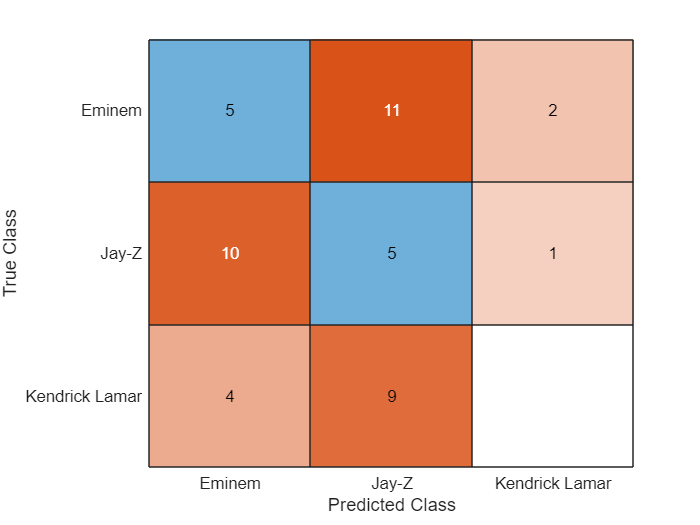


% Generate a confusion chart to visualize the performance of the classifier
confusionchart(TestData.Artist, predictions);

Based on the results we see that our model is not highly accurate and steps should be taken to improve its accuracy. This can involve feeding more training data into the model. However, a much easier step is to change the `NumNeighbors` option in the function `fitknn()`. Adjusting the number of nearest neighbor the model uses can have significant impact on accuracy. 

## Step 9: Using the Model

Some of the models you design will have more steps than the standard 8 steps introduced in sections 07 and 08, so feel free to include additional steps or skip steps that are not important to your application. In this example, we need an additional step to apply the KNN model to the data in the file `NewRapper.xlsx`. 

Write the code to read the data in `NewRapper.xlsx `and make predictions using that data. 

% Read the data from the Excel file into a table
NewRapper = readtable('NewRapper.xlsx');

% Use the trained KNN model to predict the artists for the data
predictions = predict(knnmodel, NewRapper)

predictions = 21×1 cell array
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Eminem'        }
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Eminem'        }
    {'Eminem'        }
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Kendrick Lamar'}
    {'Eminem'        }
    {'Jay-Z'         }


According to the KNN model Veeze's music is most similar to the Kendrick Lamar's music. However, we must remember that the model is not highly accurate, so these results will not be reliable unless the accuracy of the model is improved. 